# Mars Rover: Final Project

Follow the instructions provided in the course to complete your final project. 

### Load the images

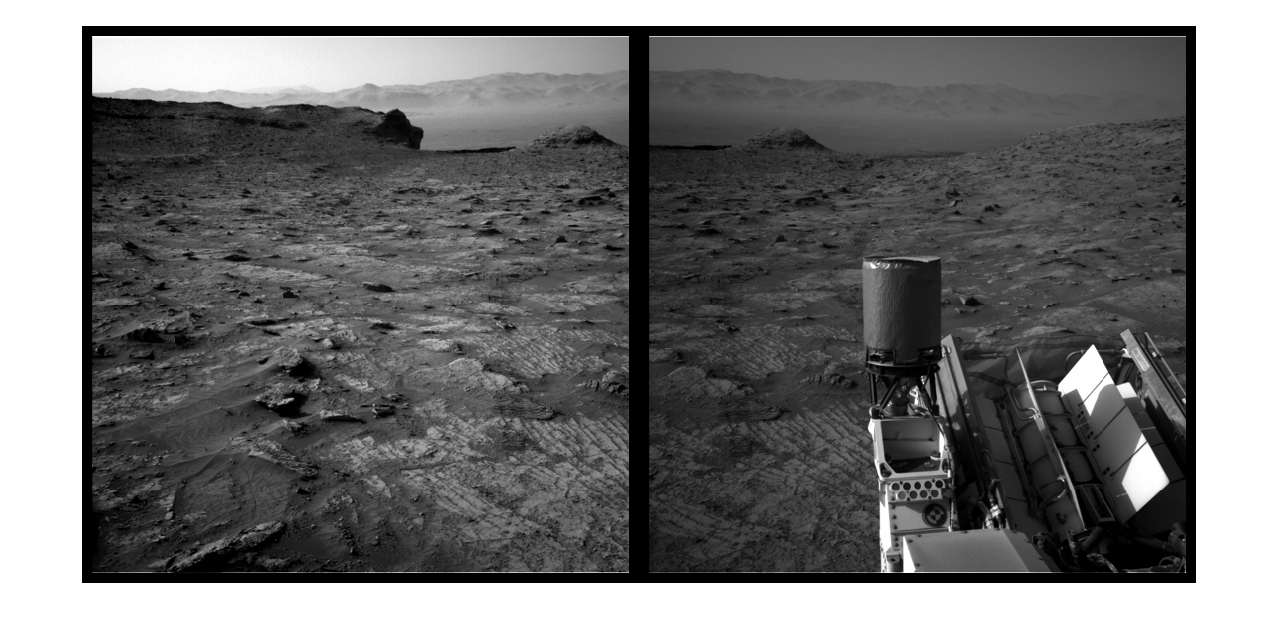

firstImg = imread("sol_03333_opgs_edr_ncam_NLB_693387301EDR_F0921230NCAM00259M_.JPG");
secondImg = imread("sol_03333_opgs_edr_ncam_NLB_693387385EDR_F0921230NCAM00259M_.JPG");
thirdImg = imread("sol_03333_opgs_edr_ncam_NLB_693387416EDR_F0921230NCAM00259M_.JPG");
montage({firstImg, secondImg},"BorderSize",[10 10])

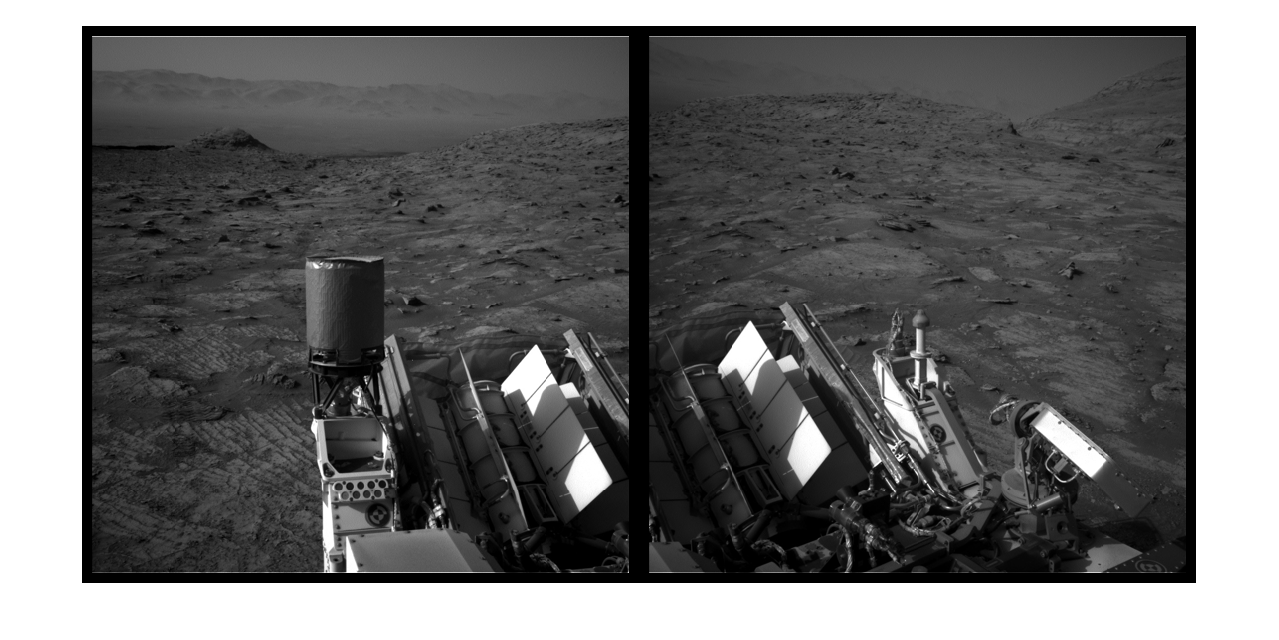

montage({secondImg, thirdImg}, "BorderSize", [10 10]);

### Register the Images

Use the Registration Estimator app to create a function that registers the images. Then, use that function to return the registration structure.

When you're happy with your registration function, return to the course and use the online grader to check if it gives the correct result.

reg12 = registerImages(firstImg, secondImg);
tform12 = reg12.Transformation;

reg32 = registerImages(thirdImg, secondImg);
tform32 = reg32.Transformation;

tforms = projective2d.empty(3,0); % empty array of correct type
tforms(1) = projective2d(tform12.T);
tforms(2) = projective2d(eye(3));
tforms(3) = projective2d(tform32.T);

### Initialize the Panorama

Use your geometric transformation to determine the world coordinates and initialize an empty panorama image. Here, recall that you're working with **grayscale** images, unlike the color concrete images.

When you're done, return to the course and take the quiz to check if your panorama dimensions are as expected.

imgs = {firstImg, secondImg, thirdImg};
imageSize = size(secondImg);

xLimits = zeros(3,2);
yLimits = zeros(3,2);
for i = 1:3
    [xLimits(i,:), yLimits(i,:)] = outputLimits(tforms(i), [1 imageSize(2)], [1 imageSize(1)]);
end

xMin = min([1; xLimits(:)]);
xMax = max([imageSize(2); xLimits(:)]);
yMin = min([1; yLimits(:)]);
yMax = max([imageSize(1); yLimits(:)]);

width  = round(xMax - xMin);
height = round(yMax - yMin);
panoramaView = imref2d([height width], [xMin xMax], [yMin yMax]);

panorama = zeros([height width], 'like', firstImg);

### Create the Panorama

Use the `vision.AlphaBlender `object to create the final panorama. When you're done, pass your final image to the `testMarsImage` function to see if it's correct. 

If you're correct, go back to the quiz and add the numeric code to complete the course!

If you get a dimension error while using `AlphaBlender`, double check that you are initializing the empty panorama correctly for a grayscale image. Remember that the third dimension of a color image has size 3, but the third dimension of a grayscale image only has size 1.

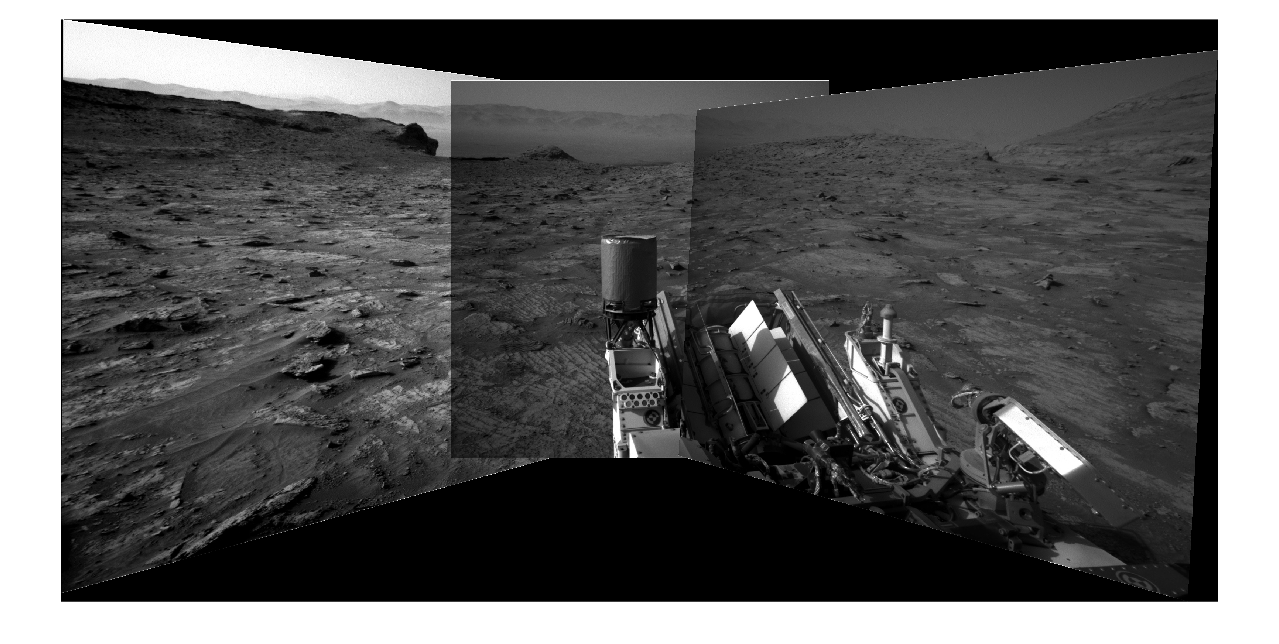

blender = vision.AlphaBlender('Operation', 'Binary mask', 'MaskSource', 'Input port');

for i = 1:3
    warpedImage = imwarp(imgs{i}, tforms(i), 'OutputView', panoramaView);
    mask = imwarp(true(size(imgs{i},1), size(imgs{i},2)), tforms(i), 'OutputView', panoramaView);
    panorama = step(blender, panorama, warpedImage, mask);
end

figure; imshow(panorama);

*Copyright 2022 The MathWorks, Inc.*